konstanten

y0 =  1;        % Amplitude in Volt (V)
f0 = 130;       % Grundfreqeunz Stimmbänder in Hertz (Hz)
fs= 20 * f0;    % Shannon-Theory (Minimu 2* f0)
nCycl = 260;    % Entspricht t=2s
phi0= 0;
dur=nCycl/f0;
disp(['Zeitliche Länge des Schallsignals in der Zeitdomäne:',num2str(dur) 's']);

Zeitliche Länge des Schallsignals in der Zeitdomäne:2s


zeitliche Länge

tol=1e-6 ;      % Schwelle für numerische Fehler
 
 
% Abtastzeiten
t=0:1/fs:dur-1/fs; %time base

berechnen, plotten, sound

y = y0*sin(2*pi*f0*t + phi0);       % Signalabtastwerte berechnen
N=length(y);                 % Anzahl der zeitdiskreten Punkte
 
figure(1)
subplot(3,2,1), plot(t(1:nCycl/4),y(1:nCycl/4),'LineWidth',1.0), grid; 
title(['Ton mit Frequenz ' num2str(f0) ' Hz '])
xlabel('Zeit t in (s)')
ylabel('Signal x(t)')
sound(y, fs)

mittlere Leistung

P=(norm(y).^2)/N;
 
disp(['Leistung des Schallsignals in der Zeitdomäne:',num2str(P)]);

Leistung des Schallsignals in der Zeitdomäne:0.5


berechnung Spektrum Zeitsignal

df=fs/N;      %Abtastfreqeunz
%Y=fft(y,N)/N; %FFT
Y=fft(y,N); %FFT
 
Pb= abs(Y);
 
% Verschiebe das Spektrum (FFTShift) symmetrisch zum Ursprung
Y=fftshift(Y);
 
sampleIndex = -N/2:(N/2-1);
f= sampleIndex * df;

plotten betrag spektrum

Yb= abs(Y);
 
subplot(3,2,2), plot(f,Yb,'LineWidth',1.0), grid; 
title(['Spektrum des Tons ' num2str(f0) ' Hz '])
xlabel('Frequency in (Hz)')
ylabel('|Y(f)|')
 
subplot(3,2,5), plot(f,Yb.^2,'LineWidth',1.0), grid; 
title(['Leistungsspektrum des Tons ' num2str(f0) ' Hz '])
xlabel('Frequency in (Hz)')
ylabel('|Y(f)|^2')
% Mittlere Leistung im Freqeunzbereich
P=norm(Yb).^2/N/N;
disp(['Leistung des Schallsignals in der Freqeunzdomäne:',num2str(P)]);

Leistung des Schallsignals in der Freqeunzdomäne:0.5


figure(1)

plotten real- und imaginärantell des spektrums

reY=real(Y);
reY(abs(reY)<tol)=0;
imY=imag(Y);
imY(abs(imY)<tol)=0;
 
 
subplot(3,2,3),plot(f,reY)
ylabel('ReY(f)')
xlabel('Frequency (Hz)')
title('Realteil des Spektrums')
subplot(3,2,4),plot(f,imY)
ylabel('ImY(f)')
xlabel('Frequency (Hz)')
title('Imaginärteil des Spektrums')

plotten und berechnen der phase des spektrums

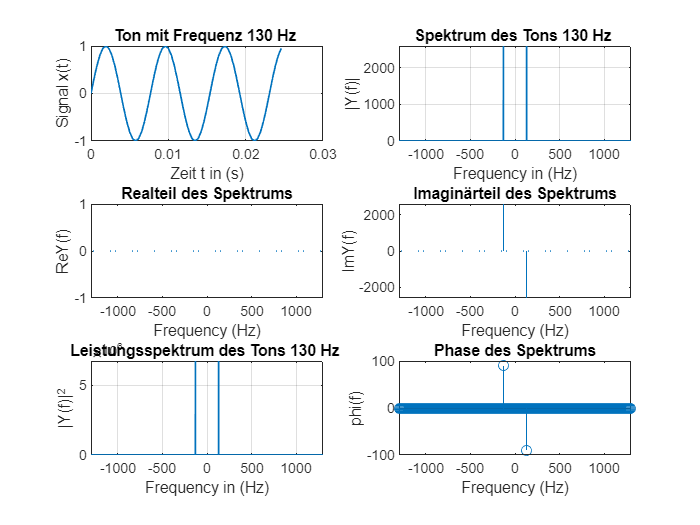

Y(abs(Y) < tol) = 0;
phi=unwrap(angle(Y)) * 180/pi;
 
subplot(3,2,6),stem(f,phi)
ylabel('phi(f)')
xlabel('Frequency (Hz)')
title('Phase des Spektrums')